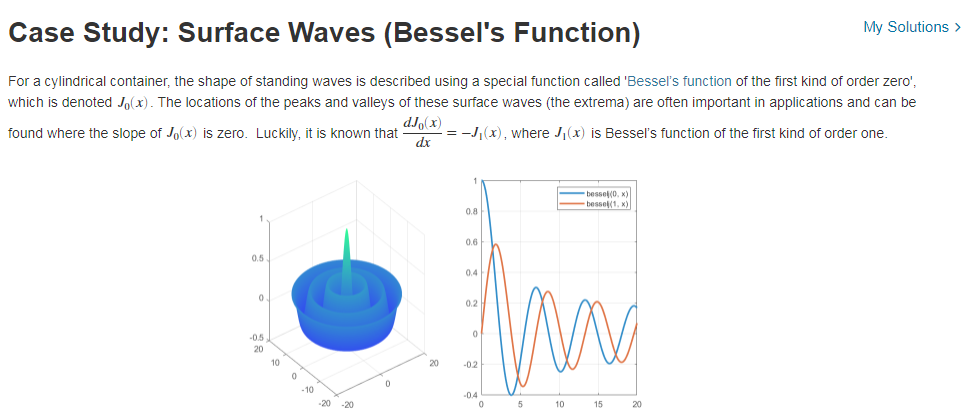

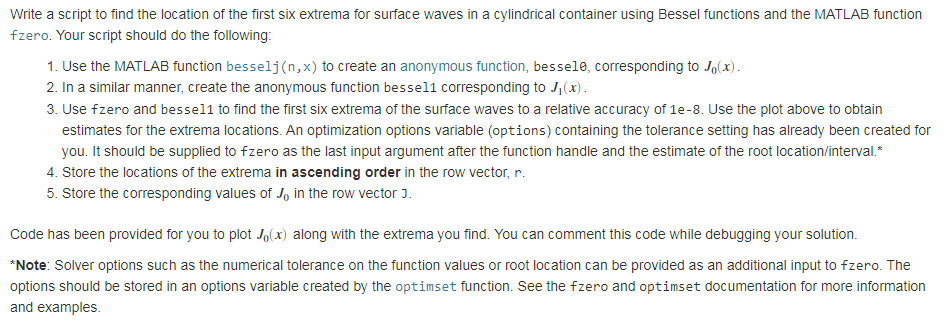

r = zeros(1,6);
J = zeros(1,6);

% Define the function handles.
bessel0 = @(x)besselj(0,x)

bessel0 = function_handle with value:
    @(x)besselj(0,x)


bessel1 = @(x)besselj(1,x)

bessel1 = function_handle with value:
    @(x)besselj(1,x)


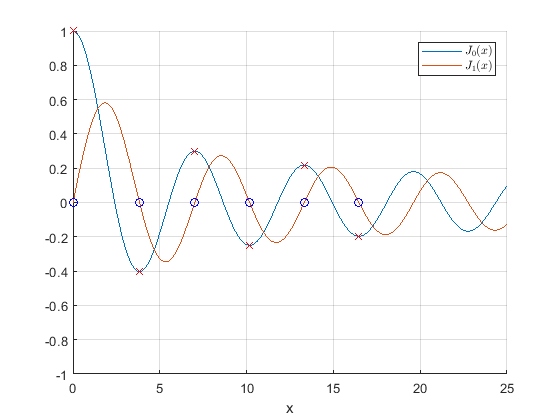


% Set the arguments for FZERO.
options = optimset('Display','none','TolX',1e-8);

% Find the first 6 extrema using FZERO.
r(1) = fzero(bessel1,[0 1],options);
r(2) = fzero(bessel1,[3 4],options);
r(3) = fzero(bessel1,[6.5 7.5],options);
r(4) = fzero(bessel1,[10 11],options);
r(5) = fzero(bessel1,[13 14],options);
r(6) = fzero(bessel1,[16 17],options);
J =  bessel0(r);


%%%%%%%%%%%  Plot the function and the extrema %%%%%%%%%%.
% Define the x values.
x = 0:0.1:25;
figure; hold on; grid on;
plot(x,bessel0(x))
plot(x,bessel1(x)),
plot(r,J,'rx');
plot(r,0*r,'bo');
axis([0 max(x) -1 1]);
xlabel('x');
legend({'$J_0(x)$','$J_1(x)$'},'Interpreter','latex')


% Print the results.
fprintf('x-location of extrema of Bessel''s function of the first kind of order zero:\n');

x-location of extrema of Bessel's function of the first kind of order zero:


fprintf('  Extrema(%d) at x = %12.8f\n',[1:length(r);r]);

  Extrema(1) at x =   0.00000000
  Extrema(2) at x =   3.83170597
  Extrema(3) at x =   7.01558667
  Extrema(4) at x =  10.17346807
  Extrema(5) at x =  13.32369201
  Extrema(6) at x =  16.47063012
